# Quickstart: Accessing Neuropixels Electrophysiology Data from the Allen Brain Observatory

This example demonstrates quick access and basic analysis of the Visual Coding Neuropixels dataset [1] from the Allen Brain Observatory [2].

### Accessing the Visual Coding Neuropixels Dataset

We can obtain information on all experimental sessions:

availSessions = bot.fetchSessions('ephys');

Fetching EPhys sessions manifest...
Fetching EPhys units manifest...
Fetching.... [4%]
Fetching.... [7%]
Fetching.... [11%]
Fetching.... [15%]
Fetching.... [18%]
Fetching.... [22%]
Fetching.... [26%]
Fetching.... [30%]
Fetching.... [33%]
Fetching.... [37%]
Fetching.... [41%]
Fetching.... [44%]
Fetching.... [48%]
Fetching.... [52%]
Fetching.... [55%]
Fetching.... [59%]
Fetching.... [63%]
Fetching.... [67%]
Fetching.... [70%]
Fetching.... [74%]
Fetching.... [78%]
Fetching.... [81%]
Fetching.... [85%]
Fetching.... [89%]
Fetching.... [92%]
Fetching.... [96%]
Fetching.... [100%]
Fetching EPhys channels manifest...
Fetching.... [4%]
Fetching.... [8%]
Fetching.... [12%]
Fetching.... [16%]
Fetching.... [20%]
Fetching.... [24%]
Fetching.... [28%]
Fetching.... [32%]
Fetching.... [37%]
Fetching.... [41%]
Fetching.... [45%]
Fetching.... [49%]
Fetching.... [53%]
Fetching.... [57%]
Fetching.... [61%]
Fetching.... [65%]
Fetching.... [69%]
Fetching.... [73%]
Fetching.... [77%]
Fetching.... [81%]
Fetch

To access probes, channels or units instead of sessions, use `bot.fetchProbes()`, `bot.fetchChannels(),` and `bot.fetchUnits()` respectively.

### Examining Sessions

#### Inspecting Available Sessions 

The information about these sessions can be displayed:

head(availSessions)

ans = 8×15 table
       id        unit_count    channel_count    probe_count        session_type         age_in_days    fail_eye_tracking    sex                      full_genotype                                                                      ephys_structure_acronyms                                                    isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _____________________    ___________    _________________    ___    _________________________________________________

#### Selecting Sessions of Interest

The table of sessions can then be filtered to obtain sessions that meet particular criteria:

% select sessions with female subjects
filteredSessions = availSessions(availSessions.sex == "F",:);

% select sessions with wild-type subjects
filteredSessions = filteredSessions(filteredSessions.full_genotype == "wt/wt",:);

% select sessions designed to investigate functional connectivity
filteredSessions = filteredSessions(filteredSessions.session_type == "functional_connectivity",:); 
disp(filteredSessions)

       id        unit_count    channel_count    probe_count         session_type          age_in_days    fail_eye_tracking    sex    full_genotype                                              ephys_structure_acronyms                                              isi_experiment_id    date_of_acquisition     specimen_id      specimen      well_known_files
    _________    __________    _____________    ___________    _______________________    ___________    _________________    ___    _____________    _______________________________________________________________________________

#### Creating Session Objects

After filtering, a session object for one particular session and its data can be created:

% sort sessions from most number of units to least and obtain one session
sortedSessions = sortrows(filteredSessions, 'unit_count', 'descend');
sessionUnderStudy = bot.session(sortedSessions(1, :));

to cache location: /external/neuralcoding/prod56/specimen_827809884/ecephys_session_847657808/EcephysWriteNwbStrategy/analysis_run_1026122155/ecephys_session_847657808.nwb...
Download complete.


sessionUnderStudy.info

ans = struct with fields:
                          id: 847657808
                  unit_count: 874
               channel_count: 2298
                 probe_count: 6
                session_type: functional_connectivity
                 age_in_days: 126
           fail_eye_tracking: 0
                         sex: F
               full_genotype: "wt/wt"
    ephys_structure_acronyms: "APN; CA1; CA3; DG; HPF; LP; MB; MGd; NOT; POST; ProS; SGN; SUB; TH; VISal; VISam; VISl; VISp; VISpm; VISrl"
           isi_experiment_id: 836962226
         date_of_acquisition: 08-Apr-2019 19:30:50
                 specimen_id: 827809884
                    specimen: [1×1 struct]
            well_known_files: [1×1 struct]


#### Inspecting Session Object Properties

The properties of the session can be displayed:

disp(sessionUnderStudy)

  EphysSession with properties:

                              info: [1×1 struct]
                                id: 847657808
                       linkedFiles: [2×1 table]

   Info Derived Values
                structure_acronyms: [1×20 string]

   Linked Items
                            probes: [6×23 table]
                          channels: [2298×29 table]
                             units: [874×51 table]

   Linked Item Derived Values


       channel_structure_intervals: [43×2 table]
         structurewise_unit_counts: [16×2 table]

   Linked File Values ('SessNWB')
      inter_presentation_intervals: '[on demand]'
                     invalid_times: '[on demand]'
                    mean_waveforms: '[on demand]'
    optogenetic_stimulation_epochs: '[on demand]'
                        pupil_data: '[on demand]'
               pupil_data_detailed: '[on demand]'
                      rig_metadata: '[on demand]'
                     running_speed: '[on demand]'
                session_start_time: '[on demand]'
                  spike_amplitudes: '[on demand]'
                       spike_times: '[on demand]'
               stimulus_conditions: '[on demand]'
                   stimulus_epochs: '[on demand]'
                    stimulus_names: '[on demand]'
            stimulus_presentations: '[on demand]'

   Linked File Values ('StimTemplatesGroup')
                stimulus_templates: '[on demand]'



### Group Analysis of Session Units

The units associated with the session can be obtained and analyzed with respect to their firing rates:

unitsTable = sessionUnderStudy.units;
head(unitsTable)

ans = 8×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio      age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio    

summary(unitsTable(:,"firing_rate"));

Description:  epoch_name_quality_metrics: complete_session - epoch_name_waveform_metrics: complete_session - quality: good - type: EPhys - published_at: 03-Oct-2019 - has_nwb: true 

Variables:

    firing_rate: 874×1 double

        Values:

            Min       0.12266 
            Median     4.9347 
            Max        57.265 



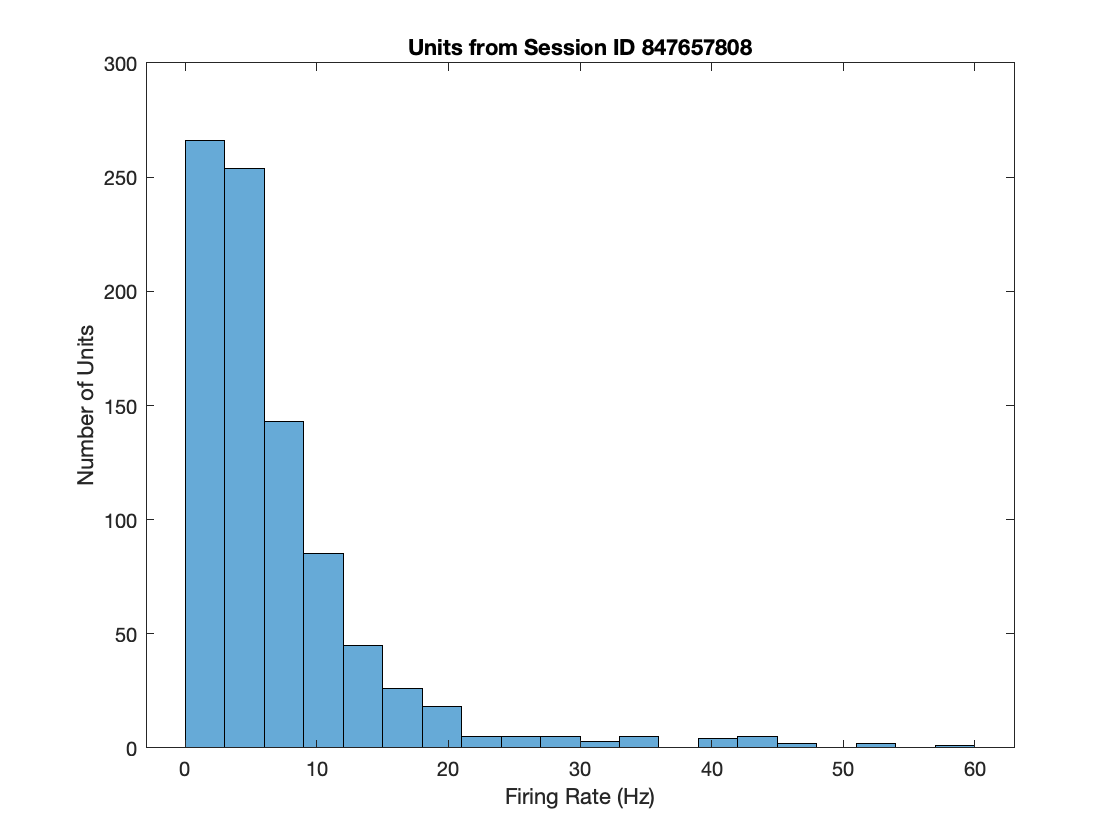

histogram(unitsTable.firing_rate);
xlabel('Firing Rate (Hz)');
ylabel('Number of Units');
title("Units from Session ID " + sessionUnderStudy.id);

### Examining Probes

The probes, which recorded data during the session, can be accessed:

probesTable = sessionUnderStudy.probes;

% obtain a `probe` object for the first probe
probeUnderStudy = bot.probe(probesTable(1, :))

Fetching OPhys manifests...


probeUnderStudy =   Probe with properties:

           info: [1×1 struct]
             id: 848037568
    linkedFiles: [1×1 table]

   Linked Items
        session: [1×1 bot.item.concrete.EphysSession]
       channels: [383×29 table]
          units: [248×51 table]

   Linked File Values ('LFPNWB')
        lfpData: '[download required]'
        csdData: '[download required]'


disp(fieldnames(probeUnderStudy.info))

    {'id'                             }
    {'ephys_session_id'               }
    {'unit_count'                     }
    {'channel_count'                  }
    {'name'                           }
    {'session_type'                   }
    {'age_in_days'                    }
    {'air_channel_index'              }
    {'fail_eye_tracking'              }
    {'has_lfp_data'                   }
    {'lfp_sampling_rate'              }
    {'lfp_temporal_subsampling_factor'}
    {'phase'                          }
    {'sampling_rate'                  }
    {'sex'                            }
    {'surface_channel_index'          }
    {'genotype'                       }
    {'ephys_structure_acronyms'       }
    {'isi_experiment_id'              }
    {'date_of_acquisition'            }
    {'specimen_id'                    }
    {'specimen'                       }
    {'well_known_files'               }



#### Probe Low Frequency Data

The probe linked file values can also be obtained:

head(probeUnderStudy.lfpData)

to cache location: /external/neuralcoding/prod56/specimen_827809884/ecephys_session_847657808/EcephysWriteNwbStrategy/analysis_run_1026122155/probe_848037568_lfp.nwb...
Download complete.


ans = 8×1 timetable
       Time       LocalFieldPotential
    __________    ___________________

    4.138 sec        [1×92 single]   
    4.1388 sec       [1×92 single]   
    4.1396 sec       [1×92 single]   
    4.1404 sec       [1×92 single]   
    4.1412 sec       [1×92 single]   
    4.142 sec        [1×92 single]   
    4.1428 sec       [1×92 single]   
    4.1436 sec       [1×92 single]   


probeUnderStudy.csdData

ans = struct with fields:
                   data: [876×1 timetable]
    horizontalPositions: [384×1 double]
      verticalPositions: [384×1 double]


### Examining Channels

The channels associated with the session can be obtained:

channelsTable = sessionUnderStudy.channels;

% obtain a `channel` object for the first channel
channelUnderStudy = bot.channel(channelsTable(1, :))

channelUnderStudy =   Channel with properties:

       info: [1×1 struct]
         id: 867380169

   Linked Items
    session: [1×1 bot.item.concrete.EphysSession]
      probe: [1×1 bot.item.Probe]
      units: [0×51 table]


disp(fieldnames(channelUnderStudy.info))

    {'id'                               }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'unit_count'                       }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'anterior_posterior_ccf_coordinate'}
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'has_lfp_data'                     }
    {'left_right_ccf_coordinate'        }
    {'lfp_sampling_rate'                }
    {'lfp_temporal_subsampling_factor'  }
    {'local_index'                      }
    {'phase'                            }
    {'probe_horizontal_position'        }
    {'probe_name'                       }
    {'probe_vertical_position'          }
    {'sampling_rate'                    }
    {'sex'                              }
    {'surface_channel_index'            }
    {'genotype'                   

### Examining Units

The units associated with the session can be obtained:

unitsTable = sessionUnderStudy.units;

% filter for units in the VISam area
filteredUnits = unitsTable(unitsTable.ephys_structure_acronym == 'VISam', :)

filteredUnits = 65×51 table
       id        ephys_channel_id    ephys_probe_id    ephys_session_id         session_type          ephys_structure_acronym     L_ratio     age_in_days    air_channel_index    amplitude_cutoff    anterior_posterior_ccf_coordinate    cumulative_drift    d_prime    dorsal_ventral_ccf_coordinate    fail_eye_tracking    firing_rate    has_lfp_data    isi_violations    isolation_distance    left_right_ccf_coordinate    lfp_temporal_subsampling_factor    max_drift    nn_hit_rate    nn_miss_rate    peak_channel    presence_ratio 

% obtain a `unit` object for the first unit
unitUnderStudy = bot.unit(filteredUnits(1, :))

unitUnderStudy =   Unit with properties:

       info: [1×1 struct]
         id: 951185413

   Linked Items
    session: [1×1 bot.item.concrete.EphysSession]
    channel: [1×1 bot.item.Channel]
      probe: [1×1 bot.item.Probe]


disp(fieldnames(unitUnderStudy.info))

    {'id'                               }
    {'ephys_channel_id'                 }
    {'ephys_probe_id'                   }
    {'ephys_session_id'                 }
    {'session_type'                     }
    {'ephys_structure_acronym'          }
    {'L_ratio'                          }
    {'age_in_days'                      }
    {'air_channel_index'                }
    {'amplitude_cutoff'                 }
    {'anterior_posterior_ccf_coordinate'}
    {'cumulative_drift'                 }
    {'d_prime'                          }
    {'dorsal_ventral_ccf_coordinate'    }
    {'fail_eye_tracking'                }
    {'firing_rate'                      }
    {'has_lfp_data'                     }
    {'isi_violations'                   }
    {'isolation_distance'               }
    {'left_right_ccf_coordinate'        }
    {'lfp_temporal_subsampling_factor'  }
    {'max_drift'                        }
    {'nn_hit_rate'                      }
    {'nn_miss_rate'               

### Conclusion

In this quickstart, the use of basic methods and the access of object properties is illustrated with limited explanation. For more details about these methods and properties, see the ephys tutorial.

### References

[1] Copyright 2019 Allen Institute for Brain Science. Visual Coding Neuropixels. Available from: [portal.brain-map.org/explore/circuits/visual-coding-neuropixels](https://portal.brain-map.org/explore/circuits/visual-coding-neuropixels).

[2] Copyright 2016 Allen Institute for Brain Science. Allen Brain Observatory. Available from: [portal.brain-map.org/explore/circuits](http://portal.brain-map.org/explore/circuits). 